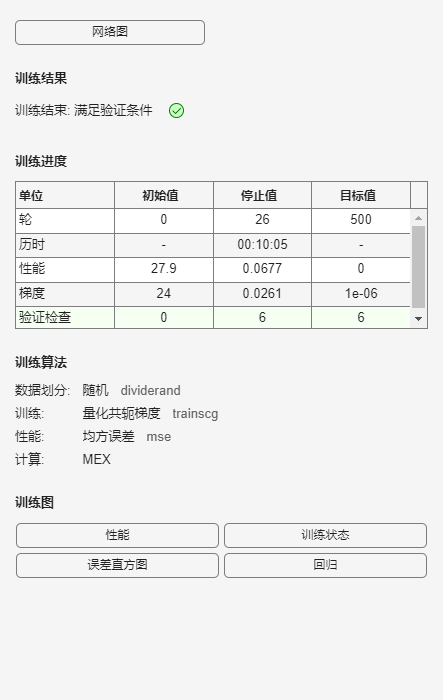

%% Hw3_Part2-3 %%% good
%% 参数设置
clc; clear; close all;

N = 400;            % 时间序列长度
rho = 0.8;          % AR(1) 系数
phi = pi/4;         % AR(2) 极点角度
sigma_alpha = 1;    % AR(1) 噪声标准差
sigma_beta = 1;     % AR(2) 噪声标准差
num_samples = 5000; % 训练样本数
hidden_layer_size = 100; % 隐藏层节点数（增加模型容量）
epochs = 500;       % 训练轮数（增加训练时间）
Y_min = 50;         % 标签归一化下限
Y_max = 350;        % 标签归一化上限

% AR(2) 系数计算
a1 = rho * cos(phi);
a2 = -rho^2 / 4;

%% 生成训练数据（保留原始统计特性）
X = zeros(num_samples, N); % 输入数据
Y = zeros(num_samples, 1); % 标签（真实 T0）

for k = 1:num_samples
    T0 = randi([Y_min, Y_max]); % 随机生成断点位置
    
    % 生成 AR(1) 数据 (n ≤ T0)
    alpha = zeros(T0, 1);
    alpha(1) = sigma_alpha * randn;
    for n = 2:T0
        alpha(n) = rho * alpha(n-1) + sigma_alpha * randn;
    end
    
    % 生成 AR(2) 数据 (n > T0)
    beta = zeros(N - T0, 1);
    if N - T0 >= 2
        beta(1) = sigma_beta * randn;
        beta(2) = sigma_beta * randn;
        for n = 3:N-T0
            beta(n) = a1 * beta(n-1) + a2 * beta(n-2) + sigma_beta * randn;
        end
    end
    
    % 拼接完整信号（不进行样本级标准化）
    x = [alpha; beta];
    X(k, :) = x;
    Y(k) = T0;
end

%% 全局标准化输入数据（所有样本统一标准化）
% 计算所有样本每个时间点的均值和标准差
X_global_mean = mean(X, 1);  % 各时间点的均值
X_global_std = std(X, 0, 1); % 各时间点的标准差
X = (X - X_global_mean) ./ X_global_std;

%% 归一化输出标签到 [0, 1]
Y_normalized = (Y - Y_min) / (Y_max - Y_min);

%% 划分训练集和测试集（8:2）
rng(0); % 固定随机种子
[trainInd, testInd] = dividerand(num_samples, 0.8, 0.2);
X_train = X(trainInd, :)';  % 输入为列向量
Y_train = Y_normalized(trainInd)';
X_test = X(testInd, :)';
Y_test = Y(testInd)';
Y_test_norm = Y_normalized(testInd)';

%% 构建神经网络
net = feedforwardnet(hidden_layer_size); % 单隐藏层网络
net.trainFcn = 'trainscg';               % 使用 SCG 优化器（适合大数据）
net.trainParam.epochs = epochs;          % 增加训练轮数
net.layers{1}.transferFcn = 'poslin';    % 隐藏层使用 ReLU
net.layers{2}.transferFcn = 'purelin';   % 输出层线性激活

%% 训练网络
[net, tr] = train(net, X_train, Y_train);


%% 测试网络
Y_pred_norm = net(X_test);               % 预测归一化标签
Y_pred = Y_pred_norm * (Y_max - Y_min) + Y_min; % 反归一化

%% 计算均方误差
mse_nn = mean((Y_pred - Y_test).^2);
fprintf('测试集 MSE: %.4f\n', mse_nn);

测试集 MSE: 7100.9871



%% 可视化结果
% 散点图：预测值 vs 真实值
figure;
scatter(Y_test, Y_pred, 20, 'filled', 'MarkerEdgeColor', 'k');
hold on;
plot([Y_min, Y_max], [Y_min, Y_max], 'r--', 'LineWidth', 1.5);
xlabel('True T_0');
ylabel('Predicted T_0');
title('Predicted vs True T_0');
grid on;
axis equal;

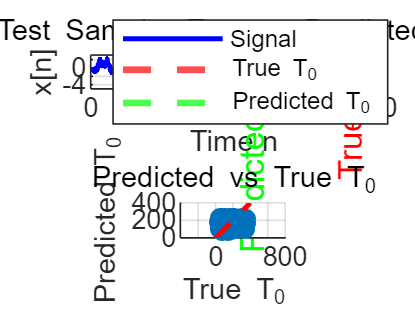


% 单样本时间序列图
idx = randi(length(Y_test)); % 随机选择一个测试样本
x_sample = X_test(:, idx);
t0_true = Y_test(idx);
t0_pred = Y_pred(idx);

figure;
subplot(2,1,1);
plot(x_sample, 'b-', 'LineWidth', 1.5);
hold on;
xline(t0_true, 'r--', 'LineWidth', 2, 'Label', 'True T_0');
xline(t0_pred, 'g--', 'LineWidth', 2, 'Label', 'Predicted T_0');
title('Test Sample: True vs Predicted T_0');
xlabel('Time n');
ylabel('x[n]');
legend('Signal', 'True T_0', 'Predicted T_0', 'Location', 'best');
grid on;